# **FEECONS Term Project**

**DAYRIT, Bettina Gaille H.**

**GUEVARRA, Gia Kyla S.**

**RODRIGUEZ, Mariah Venice A.**

**SABINO, Cleajane Y.**

**SULIT, Keane Dwight A.**

## BLOCK DIAGRAM REFERNCES

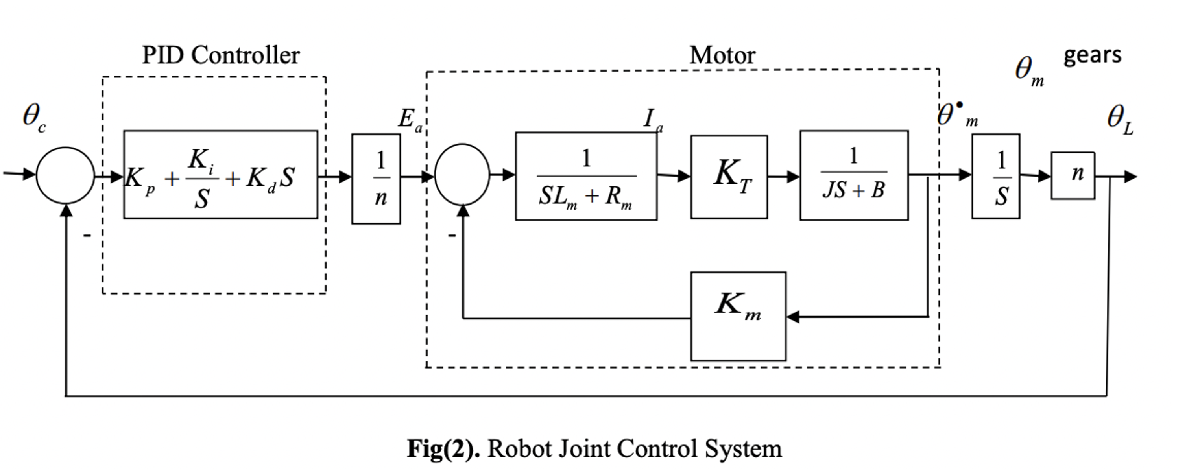

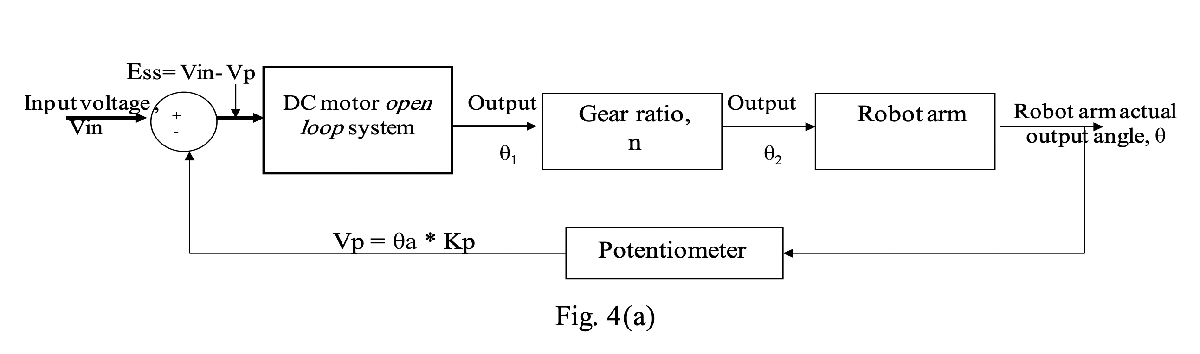

## POSITION CONTROL (ANGULAR POSITION OUTPUT)

### TRANSFER FUNCTION

The transfer function is given by the following (motor and arm)

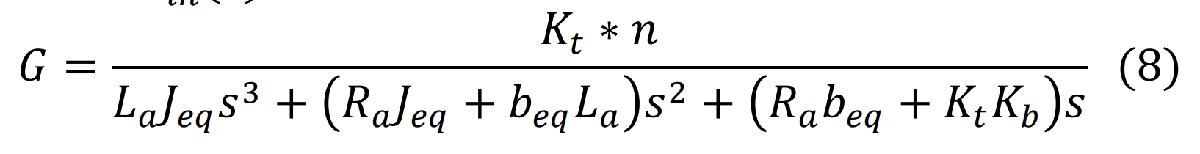

clc, clear all, close all

% Declaring nominal values of the system
J = 0.05; 
b = 0.09;
Kb = 0.020;
Kt = 0.022;
Ra = 2; % in ohms
La = 0.03; % in Henry
V = 12; % in volts
M= 10; 
b_arm= 0.03;
L = 0.5; % in m
n= 1;

% calculating Jload given by the formula, (ml^2)/12
Jload= (M*L^2)/12;

% calculating equivalent values
beq= b_arm + b*n;
Jeq= J + Jload*n;

V_max = input(' Enter maximum allowed voltage , V max : ');
Angle_max = input( 'Enter maximum allowed angle for robot arm : ');

% determining the transfer function [OPEN LOOP] 
num = [Kt*n];
den=[(La*Jeq) (Ra*Jeq+beq*La) (Ra*beq+Kt*Kb) 0];
disp('Robot arm open loop transfer function, Angle/Volt: ')

Robot arm open loop transfer function, Angle/Volt: 


Gs_OLTF =tf(num,den)

Gs_OLTF =
 
                 0.022
  -----------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s
 
Continuous-time transfer function.



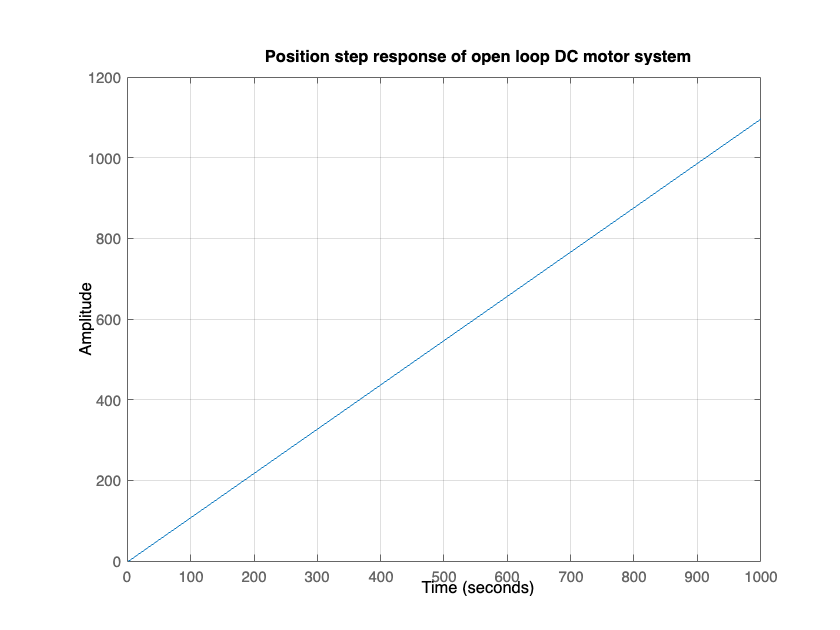

Gs_OLTFa = V*Gs_OLTF;
step(Gs_OLTFa); title('Position step response of open loop DC motor system'); grid on


% Sensor modelling, Km/Potentiometer
Km =V_max/Angle_max; % potentiometer
Gs_CLTF= feedback(Gs_OLTF,(Km/n))

Gs_CLTF =
 
                     0.022
  --------------------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s + 0.0022
 
Continuous-time transfer function.



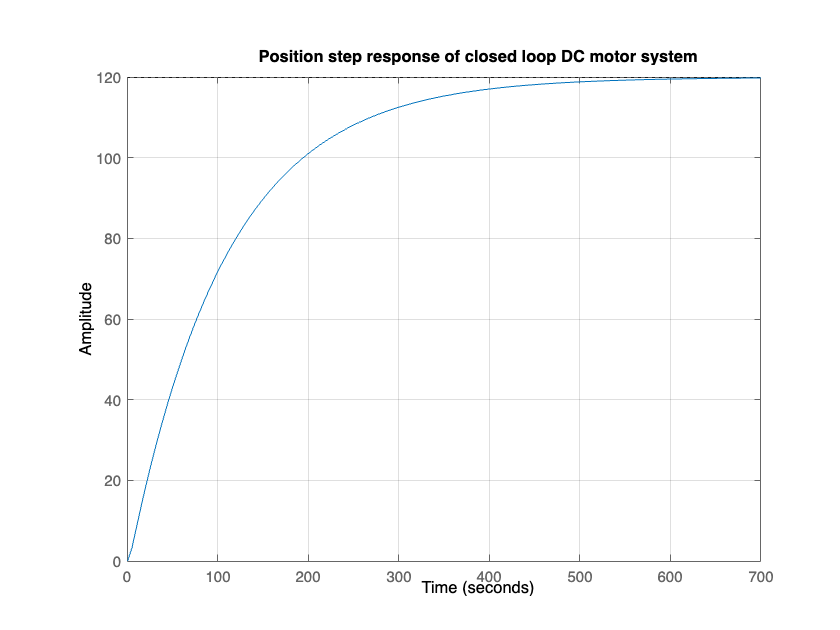

step(V*Gs_CLTF); title('Position step response of closed loop DC motor system'); grid on


% Getting Initial Time Responses
info_mtr= stepinfo(Gs_CLTF)

info_mtr = struct with fields:
         RiseTime: 235.3006
    TransientTime: 421.1685
     SettlingTime: 421.1685
      SettlingMin: 9.0249
      SettlingMax: 9.9933
        Overshoot: 0
       Undershoot: 0
             Peak: 9.9933
         PeakTime: 784.0838


% getting steady-state error
[out, t]= step(Gs_CLTF);
SP= 1;
error= abs(SP-out(end))

error = 8.9692

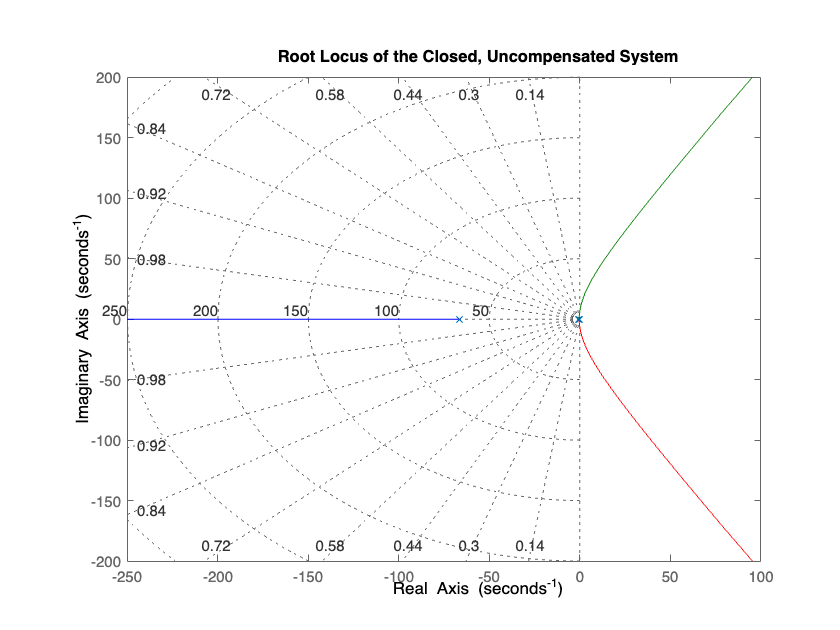


% root locus visualizations
rlocus(Gs_CLTF); grid on; title ('Root Locus of the Closed, Uncompensated System')


dena= [0.00775 0.5203 0.2404 0.0022]; % getting the precise value of the poles
poles= roots(dena)

poles =   -66.6703
   -0.4559
   -0.0093


== **VISUALIZATION**

Control System Designer

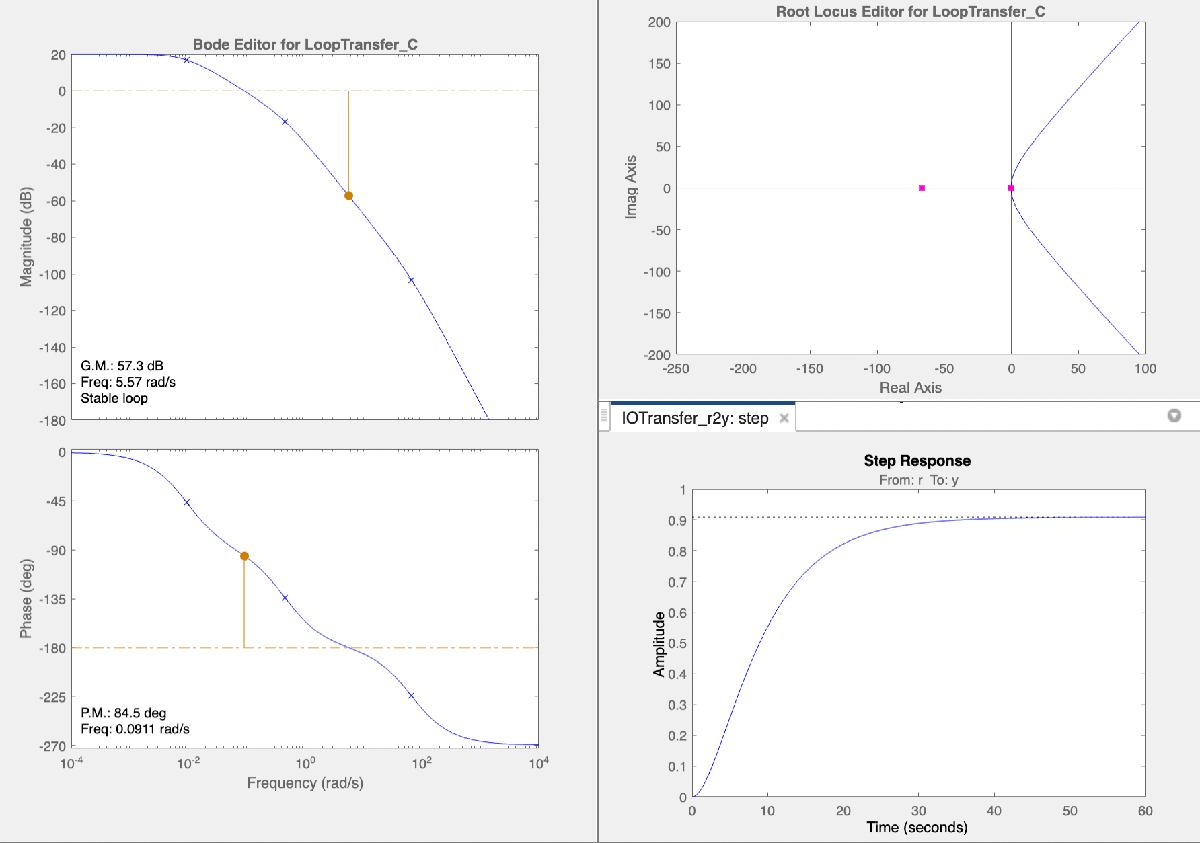

### DETERMINING THE DESIRED POLES

== **DESIGN CRITERIA:**

- Settling Time (Ts) <= 1 second

- % Overshoot <= 1%

- Steady State Error = 0.1

% ... from the given design criteria:
Ts=1;
PO=0.01;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.8261

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 4.8421

Incorporating the parameters, the given transfer function is now:

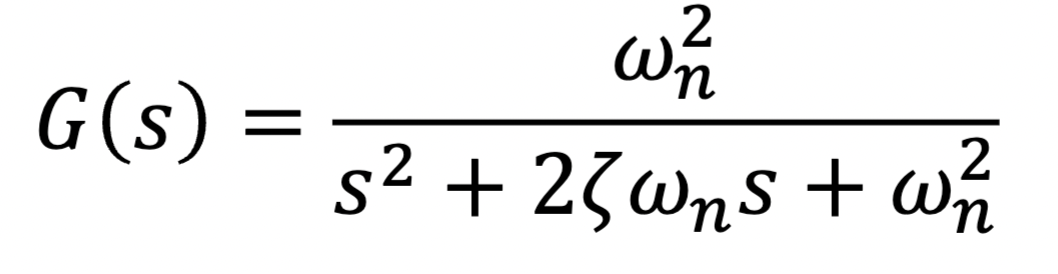

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 2.7288i
  -4.0000 - 2.7288i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 4\ldotp 1948j$ are the desired poles. 

### DESIGNING THE COMPENSATORS  

#### Designing a LEAD Compensator 

% From the poles in the system and shown in the root locus, place a zero
% close to the right most pole, P3= =-0.0093

zlead= 0.009125 % approximate (trial and error) value

zlead = 0.0091

**== VISUALIZATIONS:**

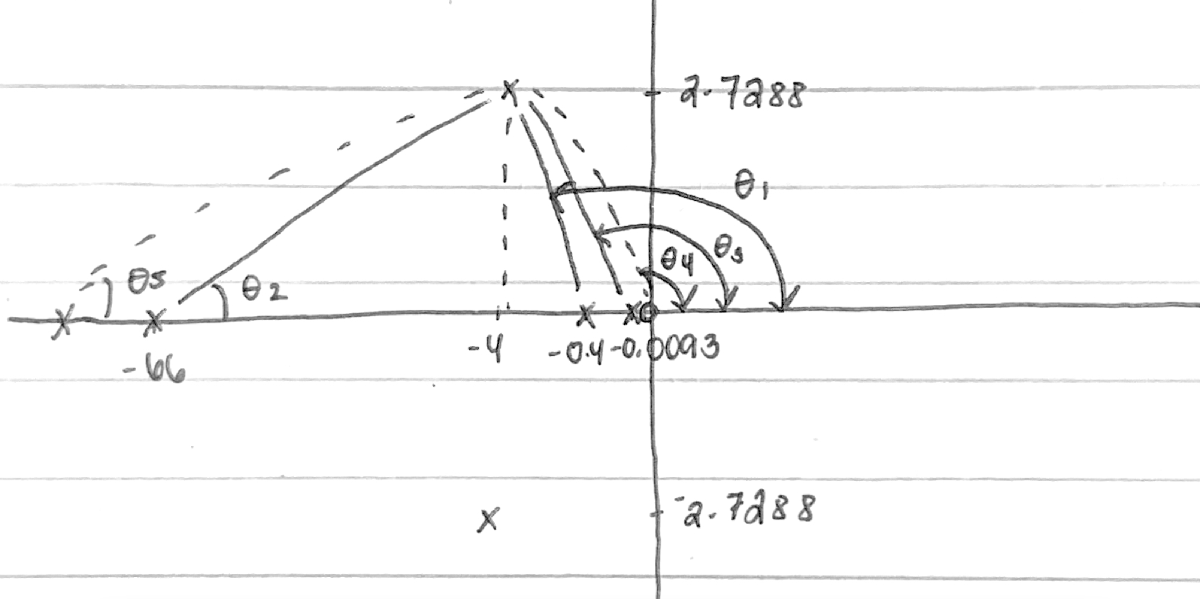

Calculations (formula) for Plead:


$$\Sigma \theta_z -\Sigma \theta_p =-180$$


θ4 - (θ1+θ2+θ3+θ5)= -180

Calculations (formula) for the overall gain, 


$$K_{\mathrm{overall}} =\frac{\mathrm{L1}\;\mathrm{L2}\;\mathrm{L3}\;\mathrm{L5}}{\mathrm{L4}}$$


% calculating for the angles
theta1= 180- rad2deg(atan(2.7288/(4-0.4559)))

theta1 = 142.4053

theta2= rad2deg(atan(2.7288/(66-4)))

theta2 = 2.5201

theta3= 180-rad2deg(atan(2.7288/(4-0.0093)))

theta3 = 145.6361

theta4= 180- rad2deg(atan(2.7288/(4-0.009125)))

theta4 = 145.6372

syms x plead
theta5= rad2deg(atan(2.7288/(plead-66)))

$$theta5 = \frac{180\,\mathrm{atan}\left(\frac{3411}{1250\,\left(\mathrm{plead}-66\right)}\right)}{\pi }$$


% solve for plead
te= theta4-(theta1+theta2+theta3);
eq= 180+te

eq = 35.0757

eqn = atan(2.7288/(x-66)) == 35.0757;
solve(eqn, x);
eqn = tan(atan(2.7288/(x-66))) == tan(35.0757);
solve(eqn, x);
double(ans)

ans = 70.7861


plead= 70.7861;

% Solving for K;

%K= ((0.0022)*(70.79))/(0.022*(0.009125))

% the given transfer function for a lead compensator is:
num2= [1 zlead];
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  s + 0.009125
  ------------
   s + 70.79
 
Continuous-time transfer function.




motortfLDC= LDCtf*Gs_CLTF % transfer function of the system compensated using a lead controller

motortfLDC =
 
                   0.022 s + 0.0002007
  ------------------------------------------------------
  0.00775 s^4 + 1.069 s^3 + 37.07 s^2 + 17.02 s + 0.1557
 
Continuous-time transfer function.



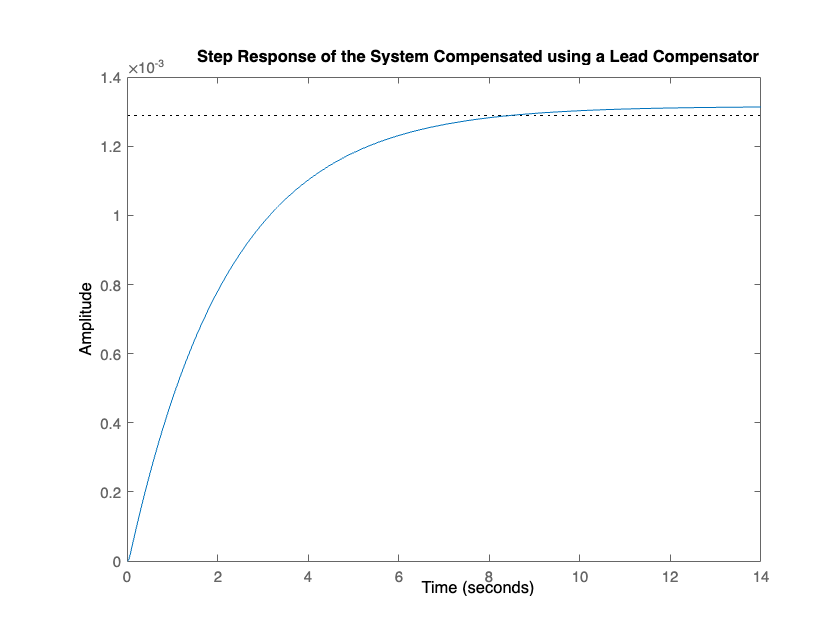


figure (1);
step(motortfLDC); title('Step Response of the System Compensated using a Lead Compensator');

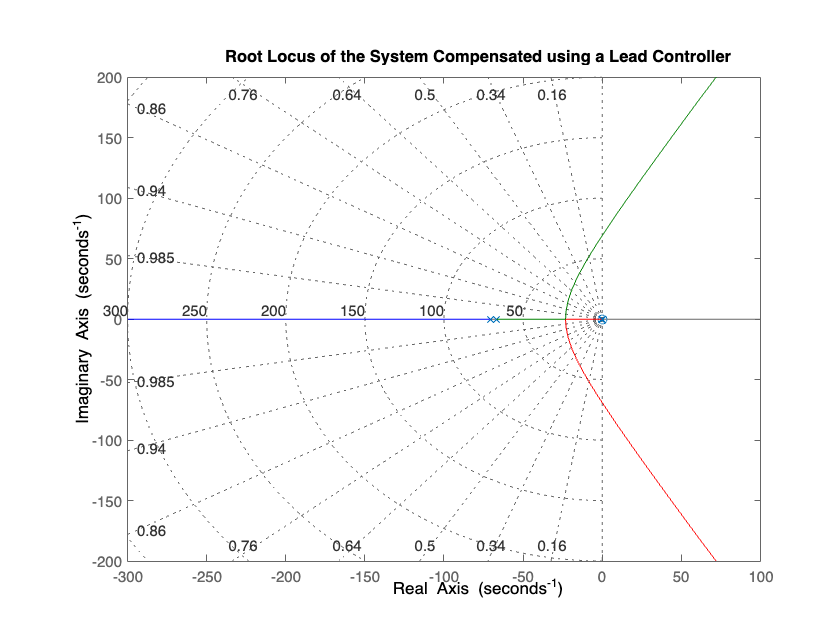

rlocus(motortfLDC); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(motortfLDC)

info_motorLDC = struct with fields:
         RiseTime: 4.4243
    TransientTime: 7.0134
     SettlingTime: 7.0134
      SettlingMin: 0.0012
      SettlingMax: 0.0013
        Overshoot: 1.9947
       Undershoot: 0
             Peak: 0.0013
         PeakTime: 17.1479


[out1, t1]= step(motortfLDC);
SP= 1;
errorLDC= abs(SP-out1(end))

errorLDC = 0.9987

**== COMMENTS**

From the given step response info: 

- Settling Time= 7.0134 ... does not satisfy the condition (<= 1 second)

- Overshoot= 1.9947 ... satisfied condition (<= 5%)

- Steady-state error= 0.9987 ...satisfied condition  (<=1)

#### Designing a LAG Compensator 

% From the computed transfer function, motortf, the system is a Type 0 system.

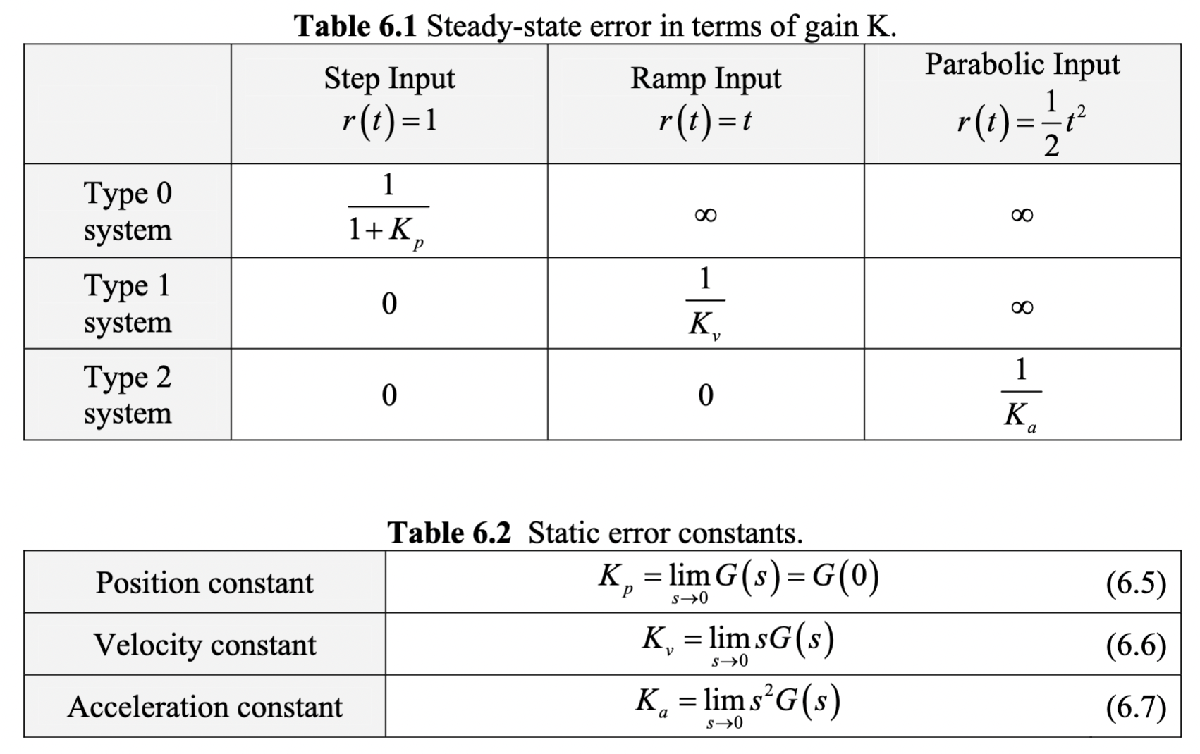

% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kv= 0.022/0.2404 % s appproaches 0, therefore s=0

Kv = 0.0915

elead= 1/Kv;
% Assume a value of Plag,
plag= 20; %**
zlag= (elead*plag)/SSE;

% the given transfer function for a lag compensator is:
num3= [1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  s + 437.1
  ---------
   s + 20
 
Continuous-time transfer function.




motortfLGC= LGCtf*Gs_CLTF % transfer function of the system compensated using a lag controller

motortfLGC =
 
                     0.022 s + 9.616
  ------------------------------------------------------
  0.00775 s^4 + 0.6753 s^3 + 10.65 s^2 + 4.811 s + 0.044
 
Continuous-time transfer function.



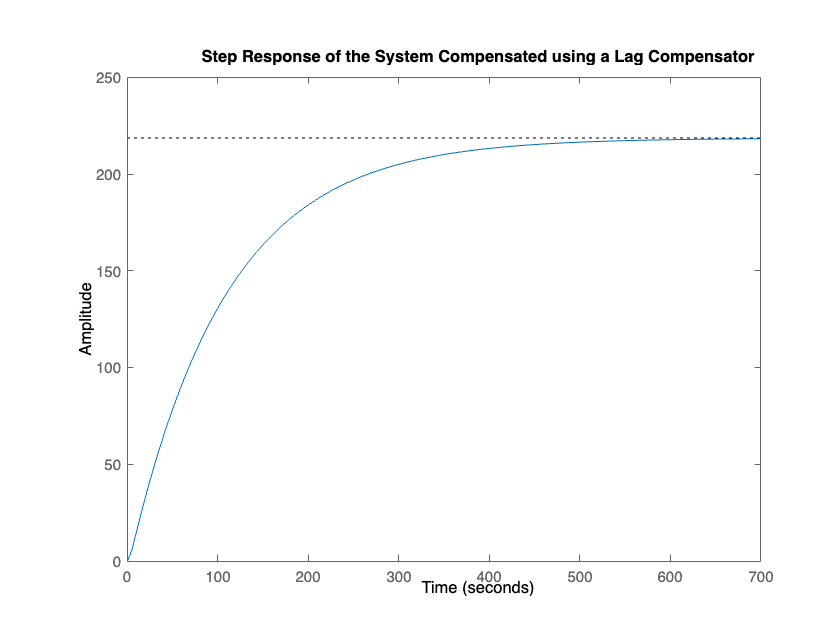


figure (2);
step(motortfLGC); title('Step Response of the System Compensated using a Lag Compensator');

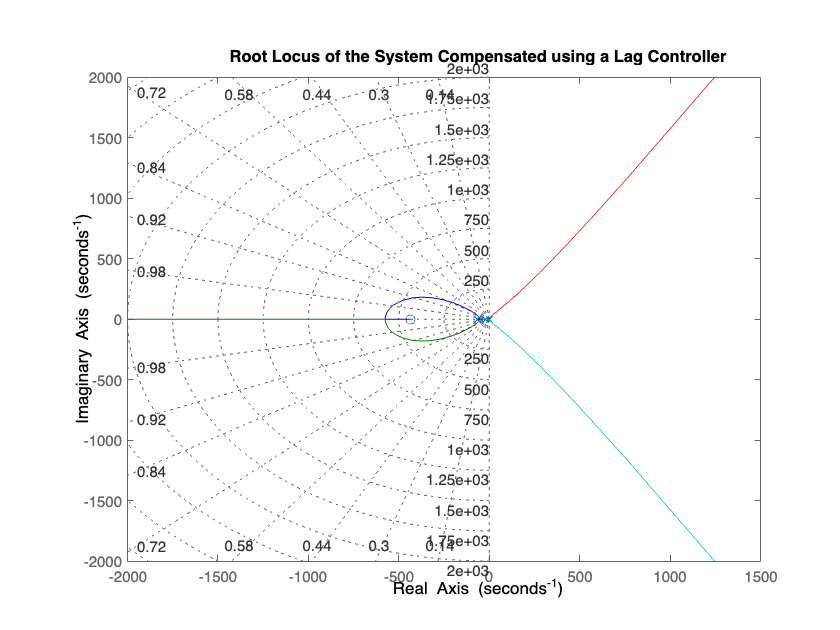

rlocus(motortfLGC); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(motortfLGC)

info_motorLGC = struct with fields:
         RiseTime: 235.3012
    TransientTime: 421.2165
     SettlingTime: 421.2165
      SettlingMin: 197.2257
      SettlingMax: 218.3980
        Overshoot: 0
       Undershoot: 0
             Peak: 218.3980
         PeakTime: 784.0838


[out2, t2]= step(motortfLGC);
SP= 1;
errorLGC= abs(SP-out2(end))

errorLGC = 216.8713

From the given step response info: 

- Settling Time= 420.7651 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.0937 ...satisfied condition  (<=1)

#### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numf= conv(num2, num3);
denf= conv(den2, den3);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  s^2 + 437.1 s + 3.988
  ---------------------
  s^2 + 90.79 s + 1416
 
Continuous-time transfer function.



motortfLDGC= Gs_CLTF*LDCtf*LGCtf

motortfLDGC =
 
                    0.022 s^2 + 9.616 s + 0.08775
  -----------------------------------------------------------------
  0.00775 s^5 + 1.224 s^4 + 58.45 s^3 + 758.4 s^2 + 340.6 s + 3.115
 
Continuous-time transfer function.



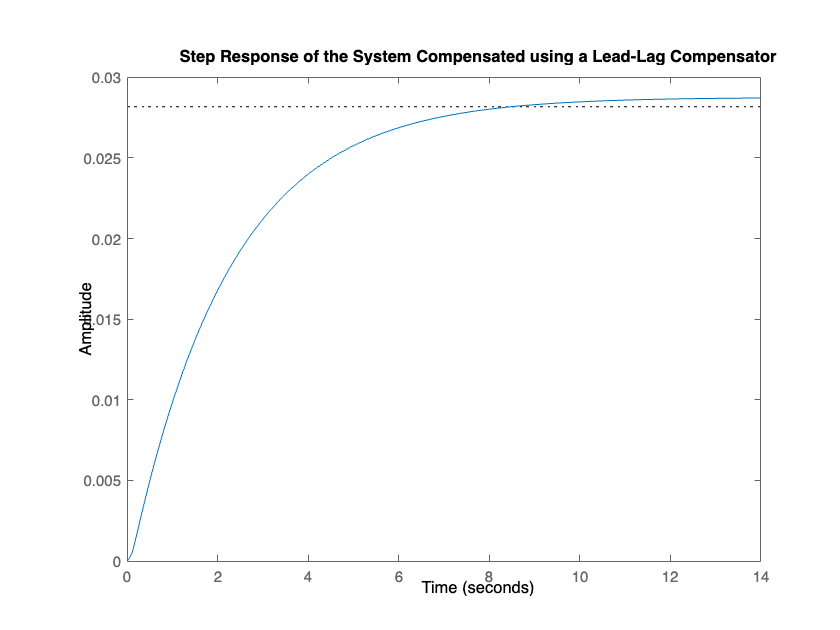

figure (3);
step(motortfLDGC); title('Step Response of the System Compensated using a Lead-Lag Compensator');

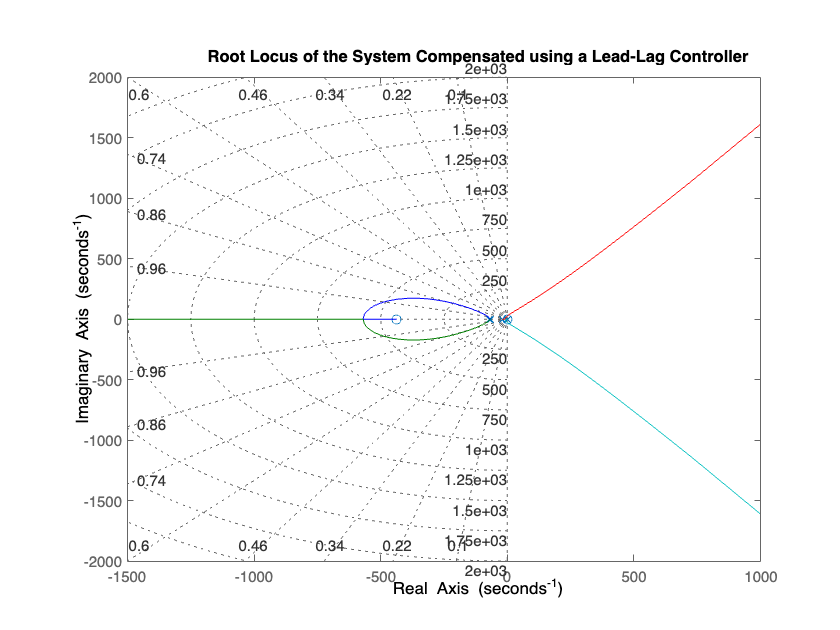

rlocus(motortfLDGC); grid on; title('Root Locus of the System Compensated using a Lead-Lag Controller');

info_motorLDGC= stepinfo(motortfLDGC)

info_motorLDGC = struct with fields:
         RiseTime: 4.4249
    TransientTime: 7.0618
     SettlingTime: 7.0618
      SettlingMin: 0.0254
      SettlingMax: 0.0287
        Overshoot: 1.9947
       Undershoot: 0
             Peak: 0.0287
         PeakTime: 17.1695


[out3, t3]= step(motortfLDGC);
SP= 1;
errorLDGC= abs(SP-out3(end))

errorLDGC = 0.9713

**== COMMENT:**

From the given step response info: 

- Settling Time= 6.5621... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.9999 ... satisfied condition (<=1%)

## SPEED CONTROL (ANGULAR VELOCITY OUTPUT)

### TRANSFER FUNCTION

The transfer function is given by the following (motor and arm)

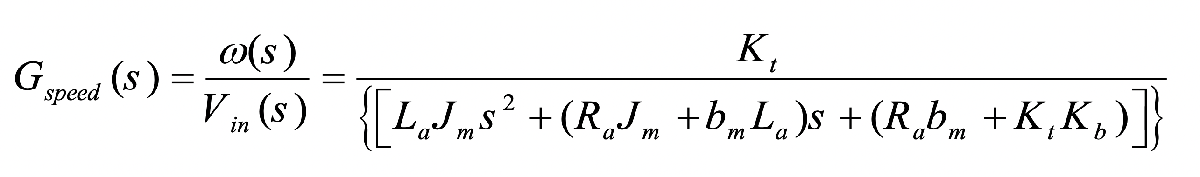

% using the same nominal values,

J = 0.05; 
b = 0.09;
Kb = 0.020;
Kt = 0.022;
Ra = 2; % in ohms
La = 0.03; % in Henry
V = 12; % in volts
M= 10; 
b_arm= 0.03;
L = 0.5; % in m
n= 1;

% calculating Jload given by the formula, (ml^2)/12
Jload= (M*L^2)/12;

% calculating equivalent values
beq= b_arm + b*n;
Jeq= J + Jload*n;

V_max = input(' Enter maximum allowed voltage , V max : ');
Angle_max = input( 'Enter maximum allowed angle for robot arm : ');

% determining the transfer function [OPEN LOOP] 
num = [Kt*n];
den=[(La*Jeq) (Ra*Jeq+beq*La) (Ra*beq+Kt*Kb)];
disp('Robot arm open loop transfer function, Angle/Volt: ')

Robot arm open loop transfer function, Angle/Volt: 


Gs_OLTF =tf(num,den)

Gs_OLTF =
 
               0.022
  -------------------------------
  0.00775 s^2 + 0.5203 s + 0.2404
 
Continuous-time transfer function.



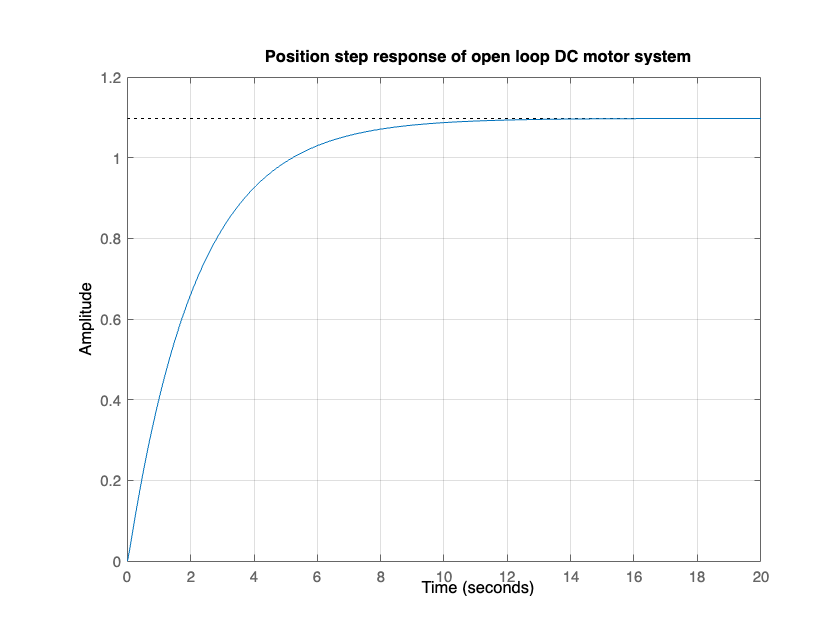

Gs_OLTFa = V*Gs_OLTF;
step(Gs_OLTFa); title('Position step response of open loop DC motor system'); grid on


% Sensor modelling, Km/Potentiometer
Km =V_max/Angle_max; % potentiometer
Gs_CLTF= feedback(Gs_OLTF,(Km/n))

Gs_CLTF =
 
               0.022
  -------------------------------
  0.00775 s^2 + 0.5203 s + 0.2426
 
Continuous-time transfer function.



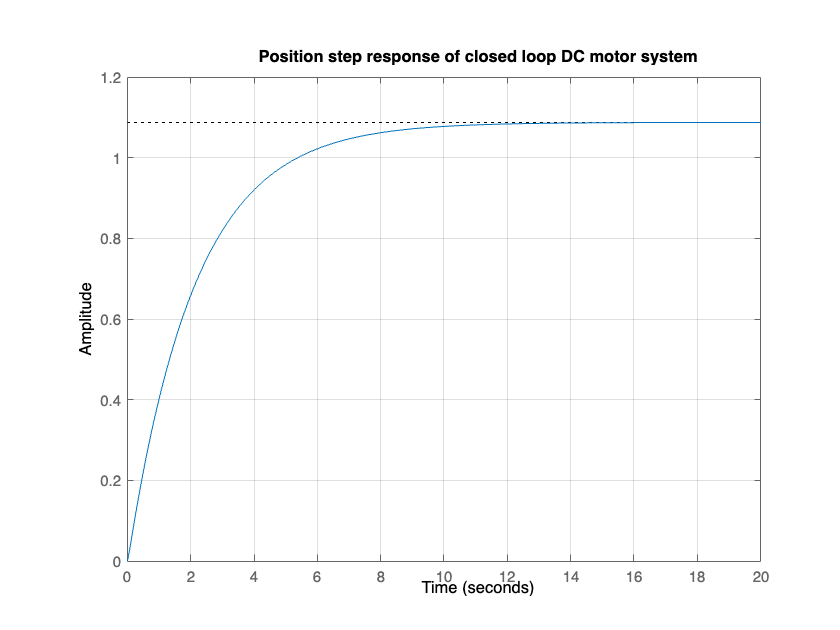

step(V*Gs_CLTF); title('Position step response of closed loop DC motor system'); grid on


% Getting Initial Time Responses
info_mtr= stepinfo(Gs_CLTF)

info_mtr = struct with fields:
         RiseTime: 4.6780
    TransientTime: 8.3447
     SettlingTime: 8.3447
      SettlingMin: 0.0819
      SettlingMax: 0.0907
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0907
         PeakTime: 22.4541


% getting steady-state error
[out, t]= step(Gs_CLTF);
SP= 1;
error= abs(SP-out(end))

error = 0.9093

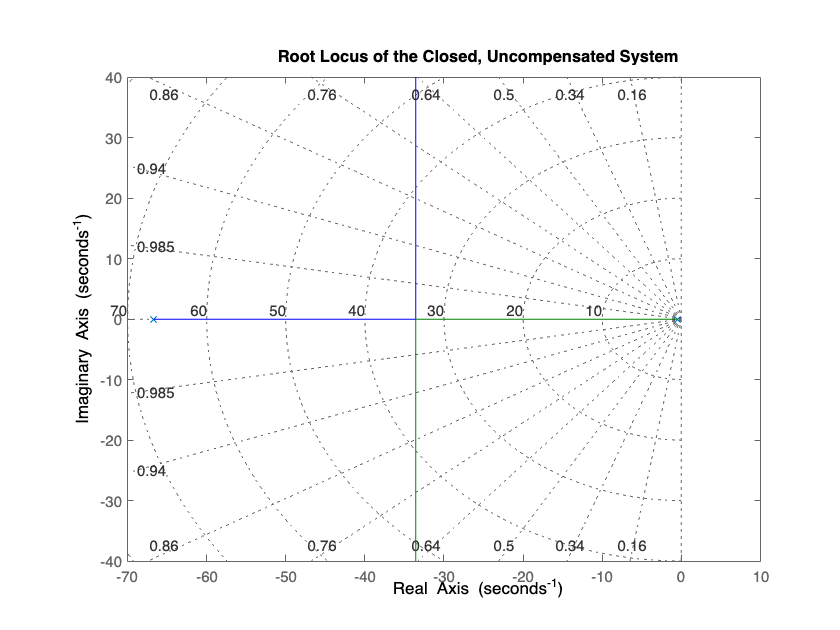


% root locus visualizations
rlocus(Gs_CLTF); grid on; title ('Root Locus of the Closed, Uncompensated System')


dena= [0.00775 0.5203 0.2426]; % getting the precise value of the poles
poles= roots(dena)

poles =   -66.6659
   -0.4696


== **VISUALIZATION**

Control System Designer

### DETERMINING THE DESIRED POLES

== **DESIGN CRITERIA:**

- Settling Time (Ts) <= 1 second

- % Overshoot <= 1%

- Steady State Error = 0

% ... from the given design criteria:
Ts=1;
PO=0.01;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.8261

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 4.8421

Incorporating the parameters, the given transfer function is now:

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 2.7288i
  -4.0000 - 2.7288i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 4\ldotp 1948j$ are the desired poles. 

### DESIGNING THE COMPENSATORS  

#### Designing a LEAD Compensator 

% From the poles in the system and shown in the root locus, place a zero
% close to the right most pole, P3= =-0.0093

zlead= 0.4696 % approximate (trial and error) value

zlead = 0.4696

**== VISUALIZATIONS:**

Calculations (formula) for Plead:


$$\Sigma \theta_z -\Sigma \theta_p =-180$$


θ1 - (θ1+θ2+θ5)= -180

Calculations (formula) for the overall gain, 


$$K_{\mathrm{overall}} =\frac{\mathrm{L1}\;\mathrm{L2}\;\mathrm{L5}}{\mathrm{L1}}$$


% calculating for the angles
theta2= rad2deg(atan(2.7288/(66-4)))

theta2 = 2.5201

syms x plead
theta5= rad2deg(atan(2.7288/(plead-66)))

$$theta5 = \frac{180\,\mathrm{atan}\left(\frac{3411}{1250\,\left(\mathrm{plead}-66\right)}\right)}{\pi }$$


% solve for plead
te= -(theta2);
eq= 180+te

eq = 177.4799

eqn = atan(2.7288/(x-66)) == 177.4799;
solve(eqn, x);
eqn = tan(atan(2.7288/(x-66))) == tan(177.4799);
solve(eqn, x);
double(ans)

ans = 66.0548


plead= 66.0548;

% Solving for K;

%L2= sqrt((2.7288)^2 + (4)^2);
%L5= sqrt((2.7288)^2 + (62.0548)^2); % the value of 80 came from plead-4 (pole)

%K= L2*L5;
%overallK= K/0.022

overallK = 1.3671e+04


% the given transfer function for a lead compensator is:
num2= [1 zlead];
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  s + 0.4696
  ----------
  s + 66.05
 
Continuous-time transfer function.




motortfLDC= LDCtf*Gs_CLTF % transfer function of the system compensated using a lead controller

motortfLDC =
 
              0.022 s + 0.01033
  -----------------------------------------
  0.00775 s^3 + 1.032 s^2 + 34.61 s + 16.03
 
Continuous-time transfer function.



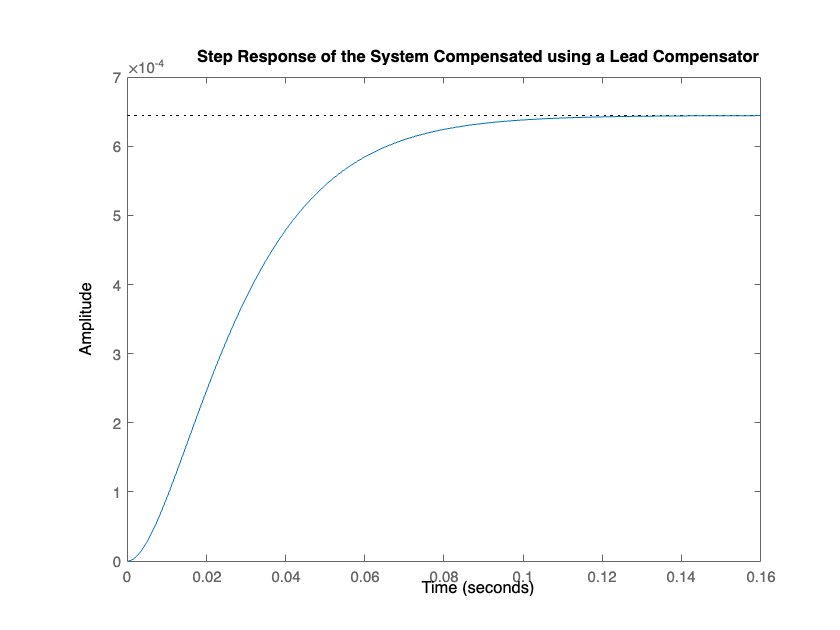


figure (1);
step(motortfLDC); title('Step Response of the System Compensated using a Lead Compensator');

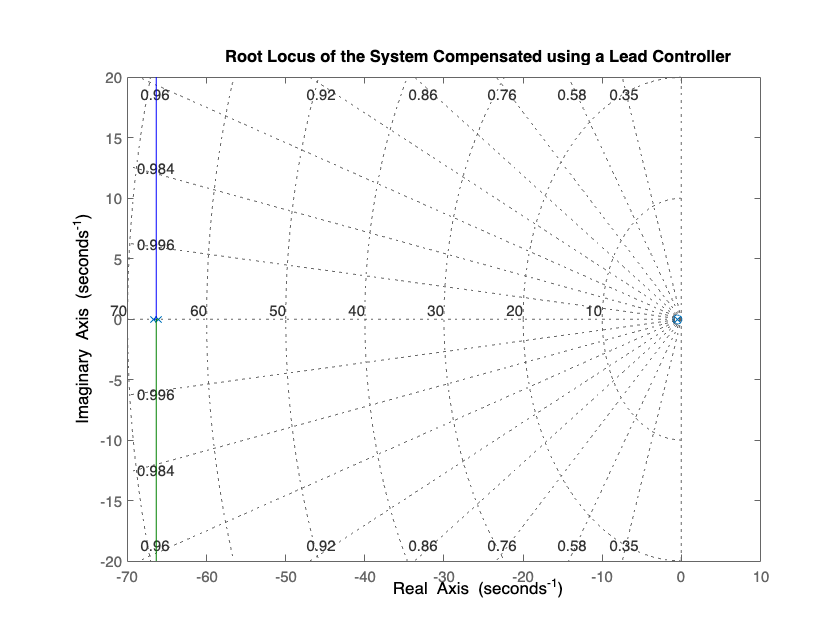

rlocus(motortfLDC); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(motortfLDC)

info_motorLDC = struct with fields:
         RiseTime: 0.0506
    TransientTime: 0.0878
     SettlingTime: 0.0878
      SettlingMin: 5.8236e-04
      SettlingMax: 6.4462e-04
        Overshoot: 0.0042
       Undershoot: 0
             Peak: 6.4462e-04
         PeakTime: 0.1806


[out1, t1]= step(motortfLDC);
SP= 1;
errorLDC= abs(SP-out1(end))

errorLDC = 0.9994

**== COMMENTS**

From the given step response info: 

- Settling Time= 0.0878 ...  satisfied  condition (<= 1 second)

- Overshoot= 0.0042... satisfied condition (<= 5%)

- Steady-state error= 0.9994...satisfied condition  (<=1)

#### Designing a LAG Compensator 

% From the computed transfer function, motortf, the system is a Type 1 system.

% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kv= 0.022/0.2404 % s appproaches 0, therefore s=0

Kv = 0.0915

elead= 1/Kv;
% Assume a value of Plag,
plag= 50; %**
zlag= (elead*plag)/SSE;

% the given transfer function for a lag compensator is:
num3= [1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  s + 546.4
  ---------
   s + 50
 
Continuous-time transfer function.




motortfLGC= LGCtf*Gs_CLTF % transfer function of the system compensated using a lag controller

motortfLGC =
 
               0.022 s + 12.02
  ------------------------------------------
  0.00775 s^3 + 0.9078 s^2 + 26.26 s + 12.13
 
Continuous-time transfer function.



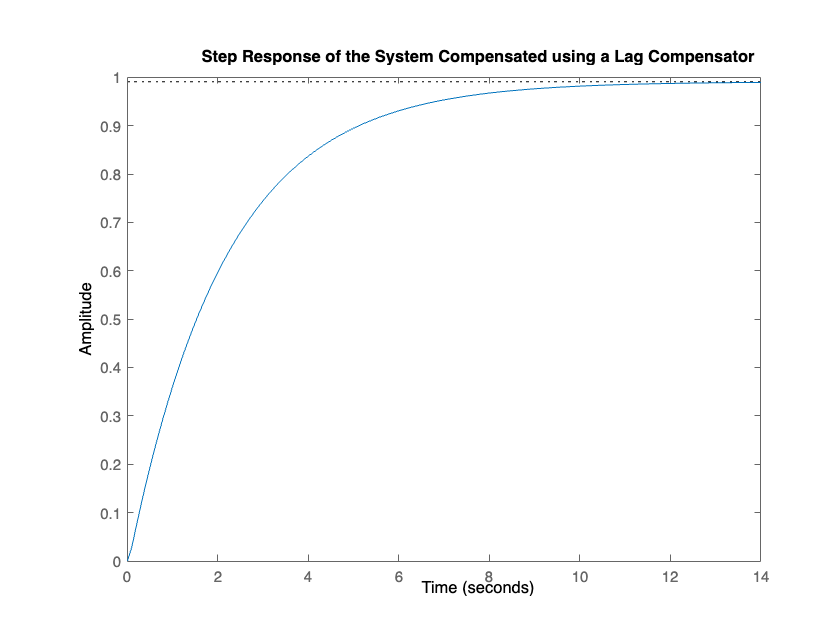


figure (2);
step(motortfLGC); title('Step Response of the System Compensated using a Lag Compensator');

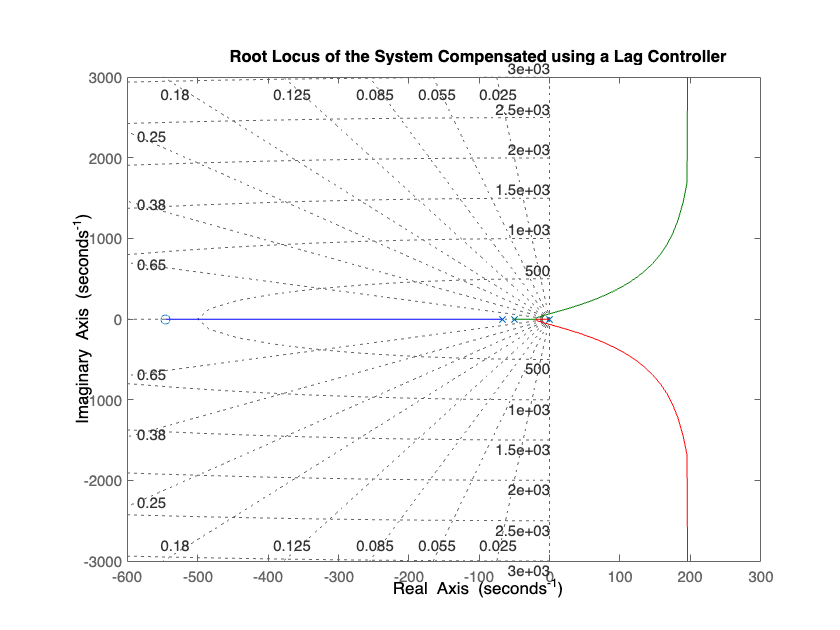

rlocus(motortfLGC); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(motortfLGC)

info_motorLGC = struct with fields:
         RiseTime: 4.6783
    TransientTime: 8.3632
     SettlingTime: 8.3632
      SettlingMin: 0.8947
      SettlingMax: 0.9901
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9901
         PeakTime: 15.5904


[out2, t2]= step(motortfLGC);
SP= 1;
errorLGC= abs(SP-out2(end))

errorLGC = 0.0123

From the given step response info: 

- Settling Time= 8.3818 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.0123 ...satisfied condition  (<=1)

#### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numf= conv(num2, num3);
denf= conv(den2, den3);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  s^2 + 546.8 s + 256.6
  ---------------------
  s^2 + 116.1 s + 3303
 
Continuous-time transfer function.



motortfLDGC= Gs_CLTF*LDCtf*LGCtf

motortfLDGC =
 
              0.022 s^2 + 12.03 s + 5.645
  ---------------------------------------------------
  0.00775 s^4 + 1.42 s^3 + 86.22 s^2 + 1746 s + 801.4
 
Continuous-time transfer function.



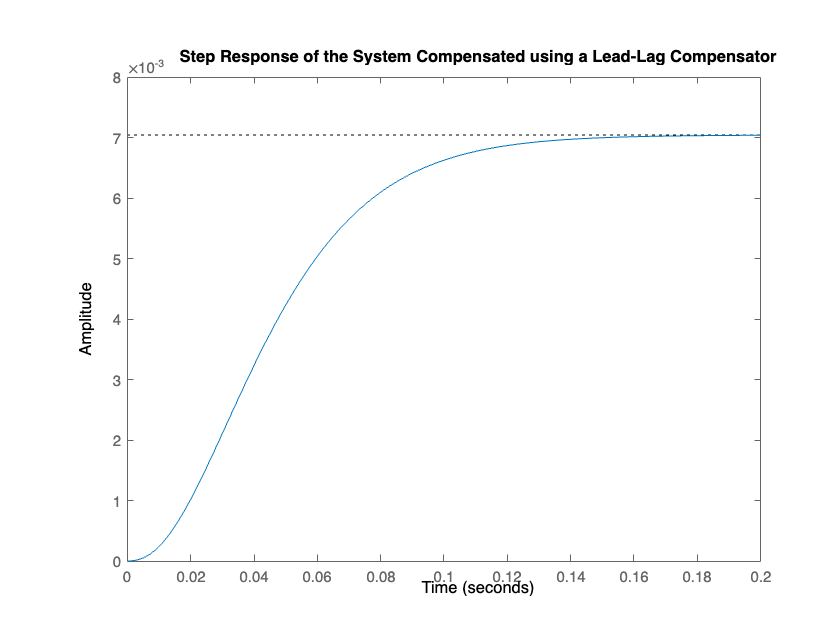

figure (3);
step(motortfLDGC); title('Step Response of the System Compensated using a Lead-Lag Compensator');

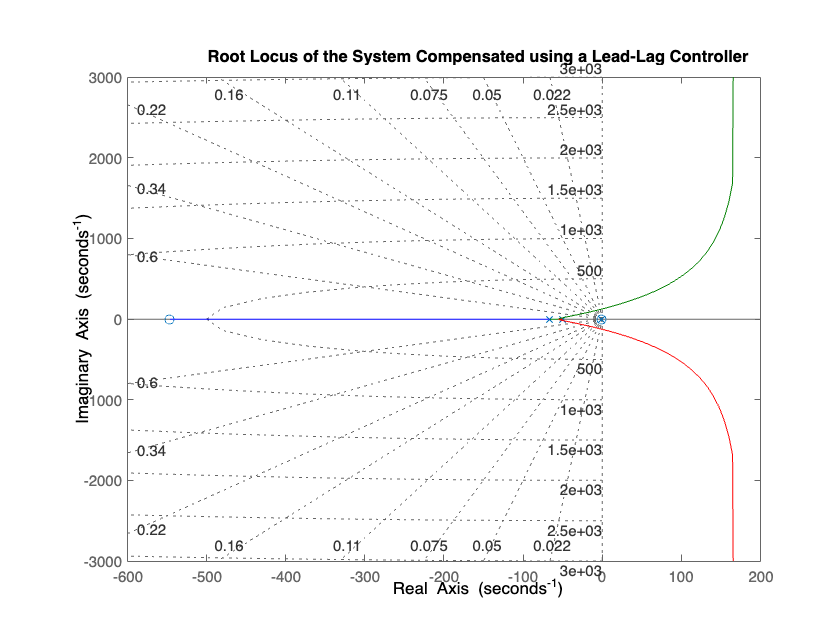

rlocus(motortfLDGC); grid on; title('Root Locus of the System Compensated using a Lead-Lag Controller');

info_motorLDGC= stepinfo(motortfLDGC)

info_motorLDGC = struct with fields:
         RiseTime: 0.0708
    TransientTime: 0.1247
     SettlingTime: 0.1247
      SettlingMin: 0.0064
      SettlingMax: 0.0070
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0070
         PeakTime: 0.2154


[out3, t3]= step(motortfLDGC);
SP= 1;
errorLDGC= abs(SP-out3(end))

errorLDGC = 0.9930

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.1247... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.9930 ... satisfied condition (<=1%)